a=1+mod(964,3);

Q1.1

[s1,fs1]=audioread("piano2.wav");
[s2,fs2]=audioread("trumpet2.wav");
[s3,fs3]=audioread("violin2.wav");
[s4,fs4]=audioread("flute2.wav");

y1=fft(s1); 
z1=fftshift(y1);
ly1=length(y1);
f_vec1=(0:ly1-1)*fs1/ly1;
amplitude_spectrum1=abs(z1)/fs1;
plot(f_vec1,mag2db(abs(amplitude_spectrum1)))
% plot(f_vec1,abs(amplitude_spectrum1))
[~, idx1] = max(abs(y1));
fundamental_frequency1= f_vec1(idx1)

fundamental_frequency1 = 523.6177

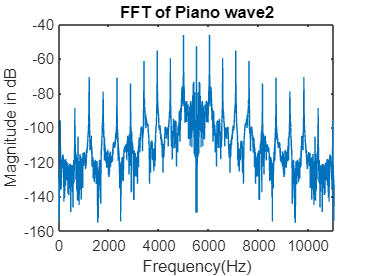

title("FFT of Piano wave2")
xlabel("Frequency(Hz)")
ylabel("Magnitude in dB")


y2=fft(s2); 
z2=fftshift(y2);
ly2=length(y2);
f_vec2=(0:ly2-1)*fs2/ly2;
amplitude_spectrum2=abs(z2)/fs2;
plot(f_vec2,mag2db(abs(amplitude_spectrum2)))
[~, idx2] = max(abs(y2));
fundamental_frequency2= f_vec2(idx2)

fundamental_frequency2 = 1.0472e+03

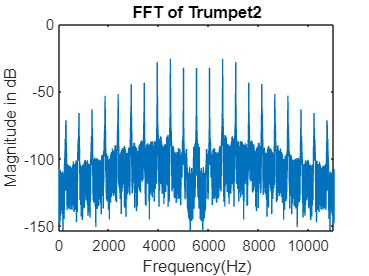

title("FFT of Trumpet2")
xlabel("Frequency(Hz)")
ylabel("Magnitude in dB")



y3=fft(s3); 
z3=fftshift(y3);
ly3=length(y3);
f_vec3=(0:ly3-1)*fs3/ly3;
amplitude_spectrum3=abs(z3)/fs3;
plot(f_vec3,mag2db(abs(amplitude_spectrum3)))
[~, idx3] = max(abs(y3));
fundamental_frequency3= f_vec3(idx3)

fundamental_frequency3 = 2.3691e+03

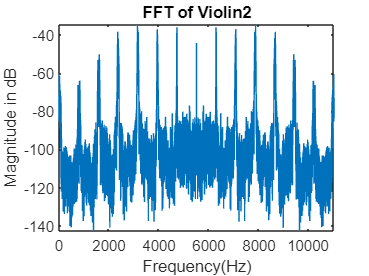

title("FFT of Violin2")
xlabel("Frequency(Hz)")
ylabel("Magnitude in dB")


y4=fft(s4); 
z4=fftshift(y4);
ly4=length(y4);
f_vec4=(0:ly4-1)*fs4/ly4;
amplitude_spectrum4=abs(z4)/fs4;
plot(f_vec4,mag2db(abs(amplitude_spectrum4)))
[~, idx4] = max(abs(y4));
fundamental_frequency4= f_vec4(idx4)

fundamental_frequency4 = 524.3338

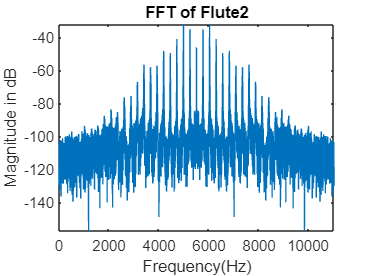

title("FFT of Flute2")
xlabel("Frequency(Hz)")
ylabel("Magnitude in dB")

Q1.2

[fl1,f1]=audioread("flute1.wav");
[fl3,f3]=audioread("flute3.wav");
[fl4,f4]=audioread("flute4.wav");

[pi1,p1]=audioread("piano1.wav");
[pi3,p3]=audioread("piano3.wav");
[pi4,p4]=audioread("piano4.wav");

lyf1=length(fl1);
f_vecf1=(0:lyf1-1)*f1/lyf1;
lyf3=length(fl3);
f_vecf3=(0:lyf3-1)*f3/lyf3;
lyf4=length(fl4);
f_vecf4=(0:lyf4-1)*f4/lyf4;

lyp1=length(pi1);
f_vecp1=(0:lyp1-1)*p1/lyp1;
lyp3=length(pi3);
f_vecp3=(0:lyp3-1)*p3/lyp3;
lyp4=length(pi4);
f_vecp4=(0:lyp4-1)*p4/lyp4;

amplitude_spectrumf1=fft(fl1);
amplitude_spectrumf3=fft(fl3);
amplitude_spectrumf4=fft(fl4);

amplitude_spectrump1=fft(pi1);
amplitude_spectrump3=fft(pi3);
amplitude_spectrump4=fft(pi4);


[~, idxf1] = max(abs(y3));
fundamental_frequencyf1= f_vecf1(idxf1)

fundamental_frequencyf1 = 2.5464e+03


[~, idxf3] = max(abs(y3));
fundamental_frequencyf3= f_vecf3(idxf3)

fundamental_frequencyf3 = 2.5122e+03


[~, idxf4] = max(abs(y3));
fundamental_frequencyf4= f_vecf4(idxf4)

fundamental_frequencyf4 = 2.5464e+03



[~, idxp1] = max(abs(y3));
fundamental_frequencyp1= f_vecp1(idxp1)

fundamental_frequencyp1 = 3.1456e+03


[~, idxp3] = max(abs(y3));
fundamental_frequencyp3= f_vecp3(idxp3)

fundamental_frequencyp3 = 8.5073e+03


[~, idxp4] = max(abs(y3));
fundamental_frequencyp4= f_vecp4(idxp4)

fundamental_frequencyp4 = 8.3182e+03


fp=[fundamental_frequencyp1 fundamental_frequency1 fundamental_frequencyp1 fundamental_frequencyp1];
ff=[fundamental_frequencyf1 fundamental_frequency4 fundamental_frequencyf3 fundamental_frequencyf4];
for i=1:4 
    b(i)=abs(fp(i)-ff(i))            
end

b =   599.1529    0.7161  633.3328  599.1529


b =   599.1529    0.7161  633.3328  599.1529


b =   599.1529    0.7161  633.3328  599.1529


b =   599.1529    0.7161  633.3328  599.1529


disp(find(b==min(b)))

     2



Q2

[w,fw]=audioread("Recording (2).m4a");
wfft = fft(w);
duration = 3; 
fs = 44100;
N_ref = length(w);
f_vec= (0:N_ref-1) * fs / N_ref;
amplitude_spectrum = abs(wfft);
[ref_max_amplitude, ref_max_amplitude_idx] = max(amplitude_spectrum);
ref_fund_freq = f_vec(ref_max_amplitude_idx)

ref_fund_freq = 1.0e+03 *

    1.3060    1.3060


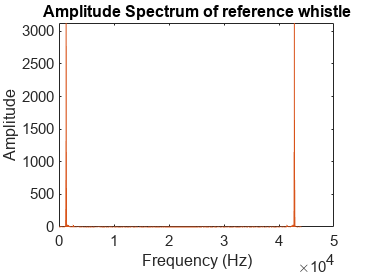

plot(f_vec,amplitude_spectrum);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Amplitude Spectrum of reference whistle');


 
recorded_audio = audiorecorder(fs,16,1);
disp('To unlock, please whistle for 3 seconds.');

To unlock, please whistle for 3 seconds.


recordblocking(recorded_audio, duration);
input_data = getaudiodata(recorded_audio);
N1 = length(input_data);
input_fft = fft(input_data);
f_vec1 = (0:N1-1) * fs / N1;
amplitude_spectrum1 = abs(input_fft);
[pks, locs] = findpeaks(amplitude_spectrum1, 'MinPeakDistance', 100);
[sorted_pks, sorted_idx] = sort(pks, 'descend');
sorted_locs = locs(sorted_idx);
fundamental_frequency_idx = sorted_locs(1);
fund_freq_input = f_vec(fundamental_frequency_idx)

fund_freq_input = 1.5760e+03


tolerance = 0.05;
if abs(fund_freq_input - ref_fund_freq) / ref_fund_freq <= tolerance
    disp('ACCESS GRANTED');
else
    disp('ACCESS DENIED');
end

ACCESS DENIED


Q3

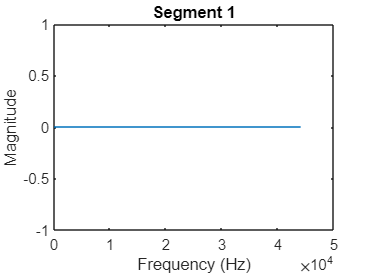

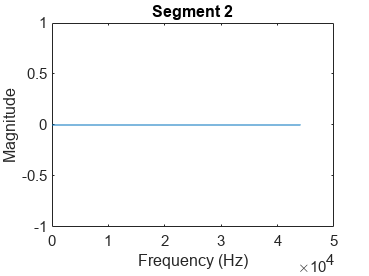

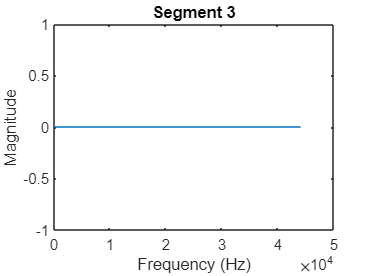

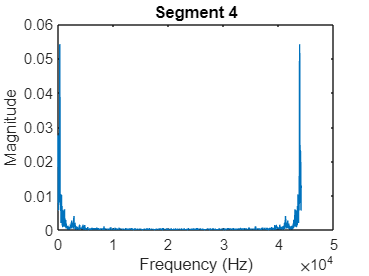

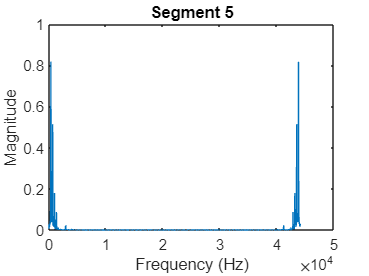

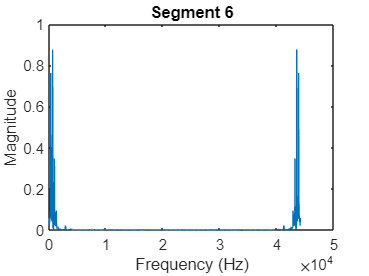

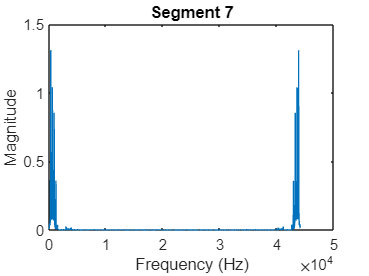

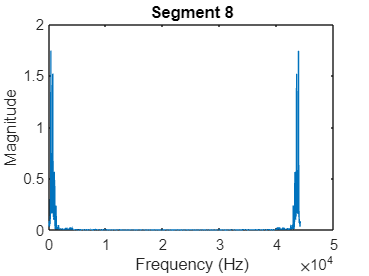

[s,fs]=audioread("opera.wav");
N=2000;
overlap=1000;
n=0:N-1;
for i = 1:10
    start_sample = (i - 1) * N + 1;
    end_sample = i * N;
    segment = s(start_sample:end_sample);
    segment_fft = fft(segment);
    f_vec = (0:N-1) * fs / N;
    figure;
    plot(f_vec, abs(segment_fft));
    xlabel('Frequency (Hz)');
     ylabel('Magnitude');
    title(['Segment ', num2str(i)]);
end

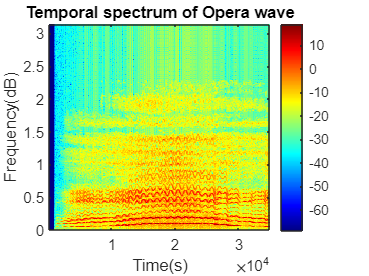

[S,F,t]=spectrogram(s,hamming(N),N/2,fs);
imagesc(t,F,10*log10(abs(S)));
axis xy;
colorbar
colormap('jet');
xlabel("Time(s)")
ylabel("Frequency(dB)")
title("Temporal spectrum of Opera wave")